# Airframe Model - State-Space Model

## Topic

This LiveScript continues with the development of your lesson on Airframes and includes the introduction of the state space formulation of your model.

## Motivation

The simple projectile in our motivational example flew in space and was only affected by the force of gravity.  Everything was easy to define in an inertial, "earth", reference frame.   The projectile was treated as a point mass and it only had three degrees of freedom.   Of course, a UAV is not a point mass and as you go through the modules, your models will develop to include many additional features, but since with each feature, everything gets more complex, this was a good place to start.   In this module, you will formulate the equations of motion in a format which more readily lends itself to adding additional features of actual UAV flight.   You will learn about state-space models and numerical solution of the governing differential equations.

## Learning Objective

In this lesson you will go through the first steps of the development of a UAV airframe model.    You will begin with a quick review of the physics of motion and the numerical solution of the underlying differential equations. By the end of this first part of the airframe module, you will be able to:

-         Write the equations of motion of a spherical mass in space, subject to gravity and drag.  

-         Formulate and solve the resulting system of state equations.

-         Understand the introduction of new state variables (Euler Angles)

## Lesson

### Utilities Used in Lesson

clear;
addpath('utils');
params=sys_params;

### Lesson A:  Development of State Space Model

#### Starting Point

In the last module, you wrote the equations of motion (using Flat Earth Coordinate System)

x-direction:   $0=m\frac{d^2 }{\mathrm{d}t^2 }x\left(t\right)$,   y-direction:   $0=m\frac{d^2 }{\mathrm{d}t^2 }y\left(t\right)$,   z-direction:    $\textrm{mg}\;a_z =m\frac{d^2 }{\mathrm{d}t^2 }z\left(t\right)$

along with initial conditions

$\left(x_0 ,\;y_0 \;,\;z_0 \right)$   and $v_{0,x} =v_0 \;\cos \left(\phi \right)\cos \left(\theta \right)$, $v_{0,y} =v_0 \;\sin \left(\phi \right)\cos \left(\theta \right)$, and $v_{0,z} =v_0 \;\sin \left(\theta \right)$

You then found the solution  


$$x\left(t\right)=x_0 +v_{x,0} \;t$$



$$y\left(t\right)=y_0 +v_{y,0} \;t$$



$$z\left(t\right)=z_0 +v_{z,0} \;t+\frac{1}{2}gt^2$$


All of this was possible because the only external force operating on the system was gravity and the projectile was modeled as a point mass.   As you develop a more sophisticated model of your UAV, it will be more convenient to address the original set of differential equations numerically.

#### Simple Illustration of the State Space Approach

To illustrate the approach, consider the differential equation

$\frac{d^2 }{\mathrm{d}t^2 }z\left(t\right)=g$   with intial conditions ${z\left(0\right)=z}_o$  and $\frac{\mathrm{d}}{\mathrm{d}t}z\;\left(t=0\right)=v_{z,0}$

You could introduce a new variable, equal to the first derivative of $z\left(t\right)$, called $v_z \left(t\right)$ and then you would have two equations

$\frac{\mathrm{d}}{\mathrm{d}t}z\left(t\right)=v_z \left(t\right)$, and


$$\frac{\mathrm{d}}{\mathrm{d}t}v_z \left(t\right)=g$$


with initial conditions ${z\left(0\right)=z}_o$  and $\;v_z \left(0\right)=v_{z,0}$

So if you solve the system of equations

$\frac{\mathrm{d}}{\mathrm{d}t}\left\lbrack \begin{array}{c}
z\\
v_z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
z\\
v_z 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
g
\end{array}\right\rbrack$    with initial conditions $\left\lbrack \begin{array}{c}
z\left(0\right)\\
v_z \left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
z_0 \\
v_{z,0} 
\end{array}\right\rbrack$

then  you have solved your original system.

### Lesson B. MATLAB Ordinary Differential Equation Solver: ode45

Throughout these lessons you will use one of the several ordinary differential equation solvers that MATLAB offers.  This is ode45.    It is an general purpose tool and will work sufficiently well for your lessons.   You may wish to use try other MATLAB differential equation solvers.

#### Solution of Simple Illustration using ode45

To use ode45, you need to write the equation as a vector equation with vector arguments

So   $\frac{\mathrm{d}}{\mathrm{d}t}\left\lbrack \begin{array}{c}
z\\
v_z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
z\\
v_z 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
g
\end{array}\right\rbrack$    becomes   $\frac{\mathrm{d}}{\mathrm{d}t}Z\left(t\right)=F\left(t,Z\right)$ and $Z\left(0\right)=\left\lbrack \begin{array}{c}
z_0 \\
v_{z,0} 
\end{array}\right\rbrack$

You could write $F\left(t,Z\right)=\textrm{AZ}\left(t\right)+f\left(t\right)$ where $A=\left\lbrack \begin{array}{cc}
0 & 1\\
0 & 0
\end{array}\right\rbrack$, but with some insight about where things are going to go as the models become more complicated, in this module you will always write the equation as $F\left(t,Z\right)=\textrm{AZ}\left(t\right)+f\left(t,Z\left(t\right)\right)$.   This has already been done for this simple example and the result is below.    

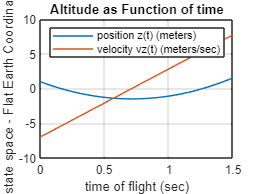

g=params.gravity;
dzdt=@(t,z)[0,1;0,0]*z+[0;g];

z0=1;     % initial position (m)
vz0= -7;    % initial velocity (m/s)
t_final=1.5; % simulation duration (sec)

tspan=[0,t_final];   Z0=[z0;vz0];
[t,Z]=ode45(dzdt,tspan,Z0);

figure
plot(t,Z); grid on;  legend('position z(t) (meters)','velocity vz(t) (meters/sec)');
xlabel('time of flight (sec)');ylabel('state space - Flat Earth Coordinates');
title('Altitude as Function of time')

### Lesson C:  State Equations for Projectile

To illustrate the development of the problem as a system of state equations, you can continue with the strategy of modeling the motion of a point mass close to the Earth and subject to its gravity plus an additional force F.   In this case, you start with $F=m*a$ and write the system.


$$\frac{d^2 }{\mathrm{d}t^2 }\left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(y\right)
\end{array}\right\rbrack =\frac{1}{m}\left\lbrace \left\lbrack \begin{array}{c}
0\\
0\\
\textrm{mg}
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
F_x \\
F_y \\
F_z 
\end{array}\right\rbrack \right\rbrace$$


where the geometry has gravity pointed in the (- z) direction and the F represents other applied forces.    By writing the equation into the vector formulation, you are preparing a formulation that will deal with additional developments as things get more sophisticated and that lends itself to a solution using ode45.  This vector formulation is easily programmed in MATLAB and you will find it understandable and efficient.

To make use of the numerical differential equation solvers, the standard approach is to rewrite this second-order ordinary differential equation (ODE) as a system of first-order ODEs.   When you introduce the time derivatives of position as velocities:


$$\left\lbrack \begin{array}{c}
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\dot{x} \left(t\right)\\
\dot{y} \left(t\right)\\
\dot{z} \left(t\right)
\end{array}\right\rbrack$$


You need to rewrite the equations into the state space formulation.    To do this, you need to write the equations in the form  $\frac{\mathrm{d}}{\mathrm{d}t}Z\left(t\right)=F\left(t,Z\right)$ and specify the inital conditions $Z\left(0\right)=Z_0$,     

The correct expression the your problem above is:


$$\frac{d}{\mathrm{d}t}\left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(t\right)\\
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(t\right)\\
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack +\frac{1}{m}\left\lbrace \left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
\textrm{mg}
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
F_x \\
F_y \\
F_z 
\end{array}\right\rbrack \right\rbrace$$


Do you see how it resembles the simple equation from our example?


$$\frac{\mathrm{d}}{\mathrm{d}t}\left\lbrack \begin{array}{c}
z\\
v_z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
z\\
v_z 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
g
\end{array}\right\rbrack$$
    

The upper half of the equations indicate the relationship between the position and the velocity.     The lower half reflect the forces and how they impact the equations of motion.

### Lesson D:  Programming State Equations:  Projectile Under Influence of Gravity

While the equation may look unnecessarily complicated or messy, it is not so bad to program.   In your first model, the projectile flies through the air, without resistance.  It has an initial velocity $v_0$ and intial angle measured from the z-axis $\theta_0$, and and initial angle measured from the x-axis of $\phi_0$.   The initial  position and initial velocity are written.


$$\left\lbrack \begin{array}{c}
x_0 \\
y_0 \\
z_0 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$$
                   
$$\left\lbrack \begin{array}{c}
v_{x0} \\
v_{y0} \\
v_{z0} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v_0 \sin \theta_0 \cos \phi_0 \\
v_0 \sin \theta_0 \sin \phi_0 \\
v_0 \cos \theta_0 
\end{array}\right\rbrack$$
      

and since your first model does not include any additional forces (beyond gravity), the terms describing these additional forces can all be set to zero.


$$\left\lbrack \begin{array}{c}
F_x \\
F_y \\
F_z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$$


#### Sample MATLAB Code

The state space equations are written in an function, dxdt0, provided along with this module.   In the exercise below, you should try to write your own version and use it along with MATLAB function **ode45()** to obtain your own solution of the system of equations.

clear
v0=8;    % m/s
thetad=152; % theta defines angle between v0 and z-axis
phid=40;   % phi defines angle between v0 and xz-plane
t_final= 2;  % duration of flight

% ---------------------------------------------------------------------------------
[~,fxyz,mxyz,kd,zdesired,kp,kv,ff]=initializeParameters;
theta=thetad*pi/180;  phi=phid*pi/180;
X0=[0;0;0]; V0=[v0*sin(theta)*cos(phi);v0*sin(theta)*sin(phi);v0*cos(theta)];
tspan=[0,t_final];
w0=[X0;V0;zeros(6,1)];


% Solved using ODE45 and a state space formulation provided along with the
% module

dxdt=@(t,w)dwdt(t,w,mxyz,fxyz,kd,ff,kp,kv,zdesired)

dxdt = function_handle with value:
    @(t,w)dwdt(t,w,mxyz,fxyz,kd,ff,kp,kv,zdesired)


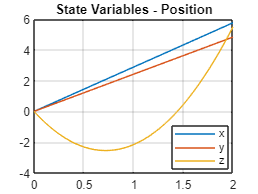


[t,XYZ]=ode45(dxdt,tspan,w0);


plot(t,XYZ(:,1:3));grid on; title('State Variables - Position'); legend('x','y','z',"Location","best");

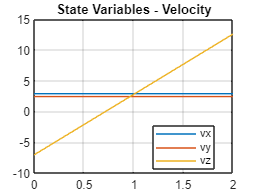

plot(t,XYZ(:,4:6));grid on; title('State Variables - Velocity'); legend('vx','vy','vz',"Location","best");

The vector of positions and velocities tells you everything about the state of the mass as it flies through space, as a function of time.   This is why it is called the*** state*** of the object, and the equations are called the ***state equations***, or state equations of motion of the object.

## Conclusion

The simple projectile in our motivational example flew in space and was only affected by the force of gravity.  Everything was easy to define in an inertial, "earth", reference frame.   The projectile was treated as a point mass and it only had three degrees of freedom.   Of course, a UAV is not a point mass and as you go through the modules, your models will develop to include many additional features, but since with each feature, everything gets more complex, this is a good place to start.  

To prepare for the next steps, you developed a state-space model that will be more easily adaptable as the complexity of the model of your UAV increases.

### Exercise

Write your own version of the derivative for the state space equations  $\frac{\mathrm{d}}{\mathrm{d}t}Z\left(t\right)=F\left(t,Z\right)$, and use ode45 to solve it in a fashion similar to the example above.

%  Your code goes here




